clear
clc
digits(4)

% Definizione del sistema:
masse_utente = [0 70 1000]; % [Kg]
altezze_utente = [1.50 1.70 1.90]; % [m]
b_var = [0 0.5 2]; % Diversi coefficienti d'attrito

Definizione costante della funzione di trasferimento G(s)

% Posizione baricentro corpo umano (da far variare)
h_c = 1.70; % Altezza uomo
% Massa uomo (da far variare)
m_c = 70;
% Angolo offset statico
alpha = 0;
b = 0;

g = 9.81;
% Massa singola ruota
m_r = 3;
% Massa asta
m_a = 3.5;
% Massa carello(base) + batterie
m_b = 34.4;
% Inerzia asta
J_a = 0.1669;
% Inerzia della base
J_b = 0.6667;
% Inerzia del corpo
J_c = 0.5 * m_c * (0.25 ^ 2 + 0.35 ^ 2);
% Inerzia della singola ruota
J_r = 0.1452;
% Altezza asta
h_a = 1.4;
% Altezza base
h_b = 0.2;
% Profondità base
w_b = 0.5;
% Posizione baricentro base (valore assoluto)
z_b = 0.1;
% Raggio ruota
r_r = 0.22;


temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;
l_c = 0.55 * h_c;
l_b = - 0.1;
l_a = (sqrt((temp_1)^2 + (temp_2)^2));
beta = (atan(temp_1 / temp_2));

% pulsazione = sqrt(D / B);
% smorzamento = - b / (2 * sqrt(B * D));

## **Simulazione *****statica senza controllo***

t_end = 100;
Ts = 1/100;
control_on = 0;
k_p = -1;

term_1 = l_c * m_c * cos(alpha);
A = l_b * m_b + term_1 + l_a * m_a * cos(beta);
A = - 8783;

term_2 = m_c * l_c^2;
B = - m_a * l_a^2 - m_b * l_b^2 - term_2 - J_a - J_b - J_c - 2 * J_r;
B = 10000;

term_3 = l_c * m_c * cos(alpha);
D = g * (l_b * m_b + term_3 + l_a * m_a * cos(beta));
D = 86160;

sim  VABSim 

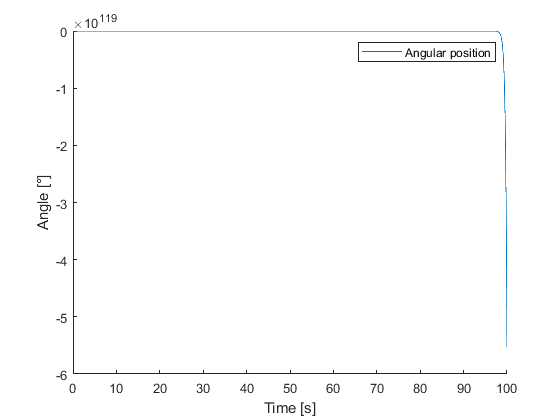

static_sim(1,:) = sim_out;
static_vel_sim(1,:) = vel_out;

figure
hold on
plot(tout, static_sim)
%plot(tout, static_vel_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('Angular position')

## **Simulazione *****statica CON controllo***

t_end = 100;
Ts = 1/100;
control_on = 1;
k_p = -1;

sim  VABSim   

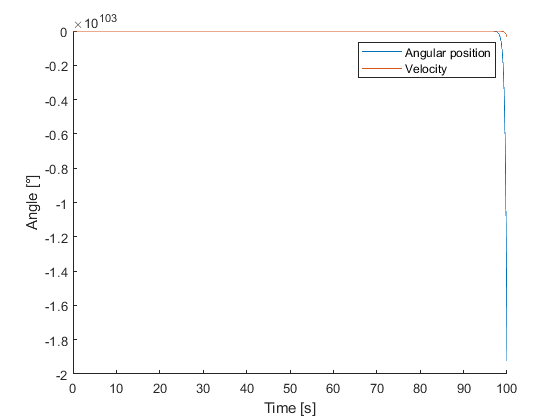

static_sim(1,:) = sim_out;
static_vel_sim(1,:) = vel_out;

figure
hold on
plot(tout, static_sim)
plot(tout, static_vel_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('Angular position','Velocity')

## **Simulazione variando la *****massa dell'utente***

t_end = 100;
Ts = 1/100;
control_on = 1;
k_p = -1;

% Simulazione al variare della massa del conducente
for i = 1 : length(masse_utente)
    masse_utente(i)
    A = l_b * m_b + l_c * masse_utente(i) * cos(alpha) + l_a * m_a * cos(beta);
    B = - m_a * l_a^2 - m_b * l_b^2 - masse_utente(i) * l_c^2 - J_a - J_b - J_c - 2 * J_r;
    D = g * (l_b * m_b + l_c * masse_utente(i) * cos(alpha) + l_a * m_a * cos(beta));
    
    sim  VABSim
    sim_various_m_c(i,:) = sim_out;
end

ans = 0

ans = 70

ans = 1000

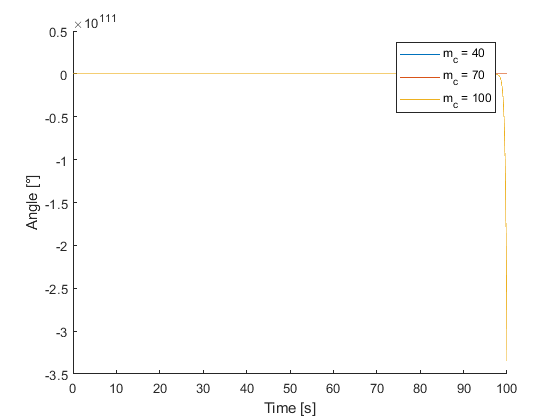


figure
hold on
plot(tout, sim_various_m_c)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('m_c = 40','m_c = 70','m_c = 100')

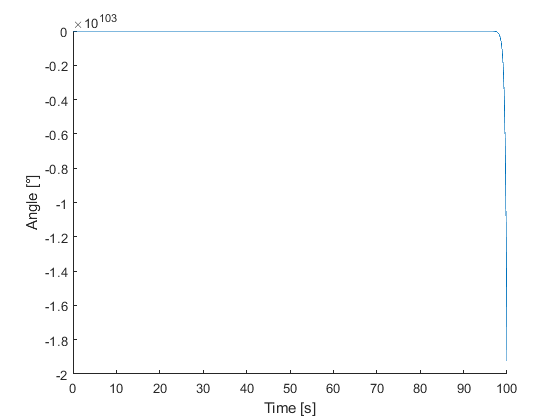

figure
hold on
plot(tout, static_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

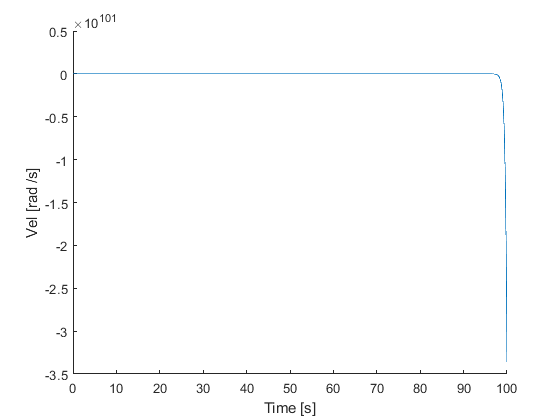


figure
hold on
plot(tout, static_vel_sim)
xlabel('Time [s]')
ylabel('Vel [rad /s]')

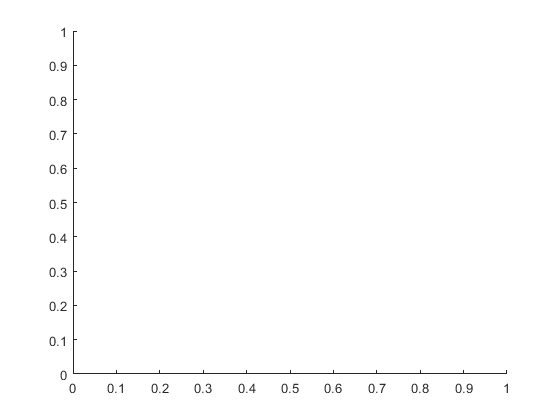



figure
hold on

plot(tout, various_l_sim)

Unrecognized function or variable 'various_l_sim'.

xlabel('Time [s]')
ylabel('Angle [°]')

legend('l = 2','l=4.5','l=7')

figure
hold on
plot(tout, various_b_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('b = 0','b=5','b=10')

% definizione sistema
s = tf('s');
l_rlocus = 1:0.5:7;

figure
hold on
sgrid on
for i=1:length(l_rlocus)
    G_s = (-1/g * s) / (l_rlocus(i)/g * s^2 + b_sim/(m_sim*l_rlocus(i)*g) * s + 1);
    rlocus(-G_s)
end

% simulazione
% smorzamento = b/(2m*sqrt(gL^3))
% puls = sqrt(g/l)

t_end = 100;
Ts = 1/100;
control_on = 1;
b_sim = b(1);
l_sim = l(3);
m_sim = m(3);

Kp_v = -[1 11 100];

%simulazione al variare di m (l = 7m b = 0)
for i = 1: length(Kp_v)
    Kp = Kp_v(i);
    
    sim  CarroponteSim
    various_Kp_sim_vel(i,:) = vel_out;
    various_Kp_sim(i,:) = sim_out;
end


figure
subplot 211
hold on
plot(tout, various_Kp_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('Kp = 1','Kp=10','Kp=100')

subplot 212
hold on
plot(tout, various_Kp_sim_vel)
xlabel('Time [s]')
ylabel('Speed []')

legend('Kp = 1','Kp=10','Kp=100')
